# Microring Resonators as analog processors - Photonic Project 2026

## Microring resonators solving first-order liner ordinary differential equation

A first-order linear ODE can be represented as: 


$$\frac{\mathrm{dy}\left(t\right)}{\mathrm{dt}}+\mathrm{ky}\left(t\right)=x\left(t\right)$$


By applying the Fourier transform, we can write the equation in the frequency domain:


$$H\left(\omega \right)=\frac{1}{k+j\omega }$$


The signal coming out from the drop port of a MRR, is described by the following equation:


$$H_{\mathrm{dr}} \left(\omega \right)=\frac{k}{k+j\left(\omega -\omega_0 \right)}$$


As we can see, these two equations are strictly correlated.

The signal coming out from the drop port of a properly designed MRR, if scaled by 1/k, it can solve a first-order linear ODE with constant-coefficient valued as k.

In our code, we implemented a class called `mrr.m`, which models a microring resonator (that uses a drop port as its output port) inside our matlab scripts.

Let's suppose, from a current driven RC circuit,  we want to find the equation that describes the voltage between the capacitance and the ground. A RC circuit is described by the following differential equation:


$$\frac{\mathrm{dy}\left(t\right)}{\mathrm{dt}}=\frac{1}{C}\left\lbrack -\frac{1}{R}y\left(t\right)+x\left(t\right)\right\rbrack$$


Where:

- $y\left(t\right)$ is the voltage of the capacitance

- $x\left(t\right)$ is the input signal (current)

- $C$ is the capacitance

- $R$ is the resistance

For simplicity, we give to ***C*** and ***R*** two made up values:

- 
$$C=1\mathrm{nF}$$


- 
$$R=16m\Omega$$


By these data, we can model a MRR made of SOI (Silicon On Insulator).

Assumptions:

- No chromatic dispersion: $n_g =n_{\mathrm{eff}}$

- Ideal case: $\alpha =0$

A=1e9;  %time scaling parameter  [nano 10^9]

k = 62.5; % ns-1
R=30e-6;  %radius of the MRR
neff=2.4;   %effective index of the MRR waveguide (SOI)

% the last value is the loss coefficient, we suppose to have no losses
MRR = mrr(R, neff, k, A, 0);

### Consideration on input bandwidth signal

We will consider the input signal $x\left(t\right)$ as a Gaussian impulse, described by the equation:


$$x\left(t\right)=\exp \left(-\log \left(2\right)*{\left(\frac{2t}{\mathrm{FWHM}}\right)}^2 \right)$$


Choosing the value of the **FWHM **is not trivial, since different values can heavily influence the output of the previously built MRR.

The FWHM controls the bandwidth of a Gaussian impulse:


$$B_{\mathrm{in}} \propto\frac{1}{\mathrm{FWHM}}$$


Now we introduce the definition of cavity lifetime:

$\tau_c =\frac{1}{k}$ (for ODE)

#### FWHM >> cavity lifetime - Integrator

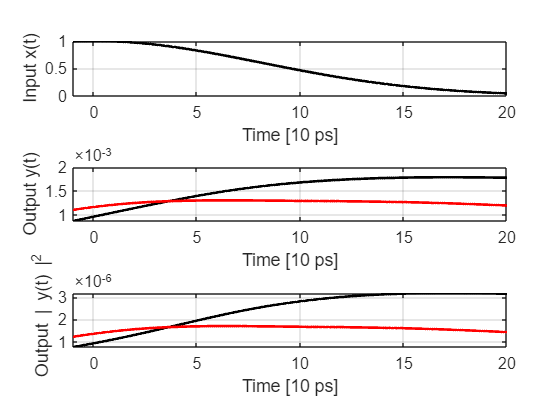

k_eq = 62.5; % ns^-1
k = 62.5;  % ns^-1
A = 1e9;  %time scaling parameter  [nano 10^9]
A_time = A * 1e4;
% Input signal x(t)

% INTEGRATOR: k >> Bs -> A_time = A * 1e4;
% FWHM = 19.07 * 1e-4;
FWHM = 19.07 * 1e-4; 


x = Model_utils.super_gaussian_function(FWHM,A);


% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

N = 1e5;
% Time span
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);

fsr = MRR.FSR(MRR.neff);
b3db = MRR.B3dB(fsr);

n_fsr_range = 1; 
dt_max = 1 / (2 * n_fsr_range * fsr);

dt = (max(t) - min(t)) / (N - 1);
if dt > dt_max
    N = ceil((max(t) - min(t)) / dt_max) + 1;
    time = linspace(min(t), max(t), N);
    dt = time(2) - time(1);
else
    time = linspace(min(t), max(t), N);
end

in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);


%% computing output

[H_drop, H_drop_norm] = MRR.h_drop_f(Df, 0);


H_ODE = MRR.h_ode(Df, 0);

Out_ring=IN_ring.*H_drop;
Out_ODE=IN_ring.*H_ODE;

Out_ring_plot = IN_ring.*H_drop_norm;

out_ring=real(ifft(ifftshift(Out_ring)));
out_ode=real(ifft(ifftshift(Out_ODE)));

out_ring_plot = real(ifft(ifftshift(Out_ring_plot)));

%% generate plots
t_min=-1;t_max=20;

utils = graph_drawer(t_min, t_max, time);

figure(1)
utils.input_output_power(in_ring, out_ring_plot,t ,y, A_time);

#### FWHM << cavity lifetime - Weighted replica of the input

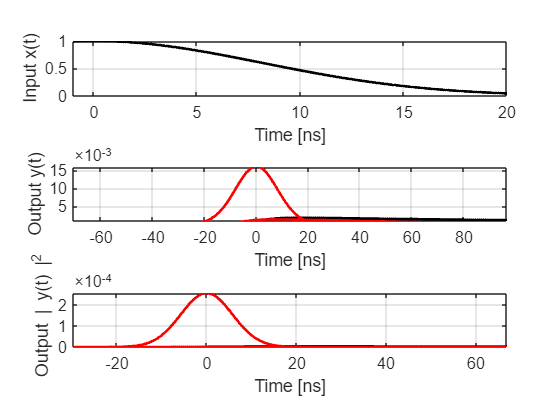

k_eq = 62.5; % ns^-1
k = 62.5;  % ns^-1
A = 1e9;  %time scaling parameter  [nano 10^9]
A_time = A;
% Input signal x(t)

% SCALER: k << Bs -> A_time = A;
% FWHM = 19.07;
FWHM = 19.07; 


x = Model_utils.super_gaussian_function(FWHM,A);


% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

N = 1e5;
% Time span
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);

fsr = MRR.FSR(MRR.neff);
b3db = MRR.B3dB(fsr);

n_fsr_range = 1; 
dt_max = 1 / (2 * n_fsr_range * fsr);

dt = (max(t) - min(t)) / (N - 1);
if dt > dt_max
    N = ceil((max(t) - min(t)) / dt_max) + 1;
    time = linspace(min(t), max(t), N);
    dt = time(2) - time(1);
else
    time = linspace(min(t), max(t), N);
end

in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);


%% computing output

[H_drop, H_drop_norm] = MRR.h_drop_f(Df, 0);


H_ODE = MRR.h_ode(Df, 0);

Out_ring=IN_ring.*H_drop;
Out_ODE=IN_ring.*H_ODE;

Out_ring_plot = IN_ring.*H_drop_norm;

out_ring=real(ifft(ifftshift(Out_ring)));
out_ode=real(ifft(ifftshift(Out_ODE)));

out_ring_plot = real(ifft(ifftshift(Out_ring_plot)));

%% generate plots
t_min=-1;t_max=20;

utils = graph_drawer(t_min, t_max, time);

figure(1)
utils.input_output_power(in_ring, out_ring_plot,t ,y, A_time);

#### FWHM approximately as cavity lifetime - ODE solver

k_eq = 62.5; % ns^-1
k = 62.5;  % ns^-1
A = 1e9;  %time scaling parameter  [nano 10^9]
A_time = A * 1e-3;
% Input signal x(t)

% ODE SOLVER: k = Bs -> A_time = A * 1e3;
% FWHM = 19.07 * 1e-3;
FWHM = 19.07 * 1e-3; 


x = Model_utils.super_gaussian_function(FWHM,A);


% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

N = 1e5;
% Time span
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);

fsr = MRR.FSR(MRR.neff);
b3db = MRR.B3dB(fsr);

n_fsr_range = 1; 
dt_max = 1 / (2 * n_fsr_range * fsr);

dt = (max(t) - min(t)) / (N - 1);
if dt > dt_max
    N = ceil((max(t) - min(t)) / dt_max) + 1;
    time = linspace(min(t), max(t), N);
    dt = time(2) - time(1);
else
    time = linspace(min(t), max(t), N);
end

in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);


%% computing output

[H_drop, H_drop_norm] = MRR.h_drop_f(Df, 0);


H_ODE = MRR.h_ode(Df, 0);

Out_ring=IN_ring.*H_drop;
Out_ODE=IN_ring.*H_ODE;

Out_ring_plot = IN_ring.*H_drop_norm;

out_ring=real(ifft(ifftshift(Out_ring)));
out_ode=real(ifft(ifftshift(Out_ODE)));

out_ring_plot = real(ifft(ifftshift(Out_ring_plot)));

%% generate plots
t_min=-1;t_max=20;

utils = graph_drawer(t_min, t_max, time);

figure(1)
utils.input_output_power(in_ring, out_ring_plot,t ,y, A_time);

## Extension to N-th order

## LTI solver